# Analisi cinematica con parametrizzazione local POE ed integrazione CLICK

#### Studio di un ABB robot: https://www.youtube.com/watch?v=cR-YlZ9NdIA

Scrittura delle costanti del robot: matrici di offset e twist unitari in terna locale

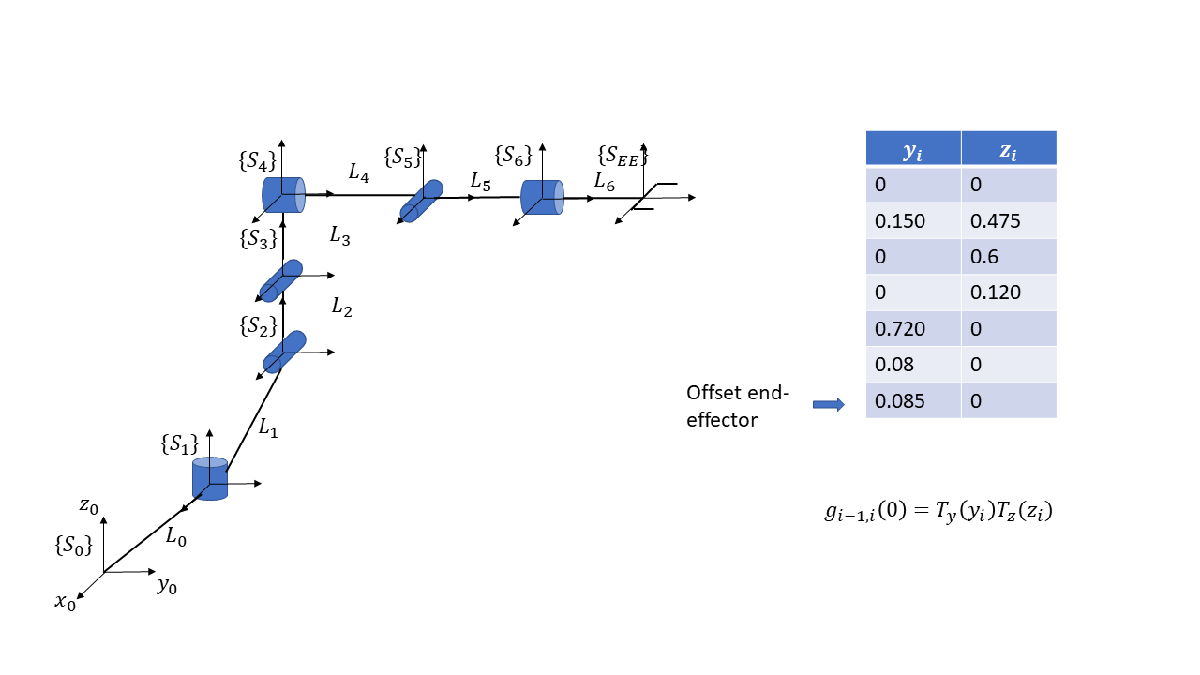

% levare commento qualora  si voglia
% automaticamente inserire il path di tutte le cartelle e sotto cartelle
% addpath(genpath(pwd))

clc; clear all;
y = [0, 0.150,   0,     0, 0.720,  0.08, 0.085];
z = [0, 0.475, 0.6, 0.120,     0,  0,     0];

g0 = cell(1,7);
for i = 1:7
    g0{i} = Tty(y(i))*Ttz(z(i));
end

X = [[0;0;0;0;0;1],[0;0;0;1;0;0],[0;0;0;1;0;0],[0;0;0;0;1;0],[0;0;0;1;0;0],[0;0;0;0;1;0]];

Analisi di postura

import casadi.*
q = SX.sym('q', 6, 1); % joint variables
t = SX.sym('t');       % time variable
[Gglobal, Glocal] = FWkin_localPOE(g0, X, q);
Gglobal = Gglobal*g0{7};   % offset transform
GlocalFun = Function('Gl', {q}, {[Glocal{:}]}); % sym expression to function

Analisi cinematica differenziale: calcolo jacobiano spatial

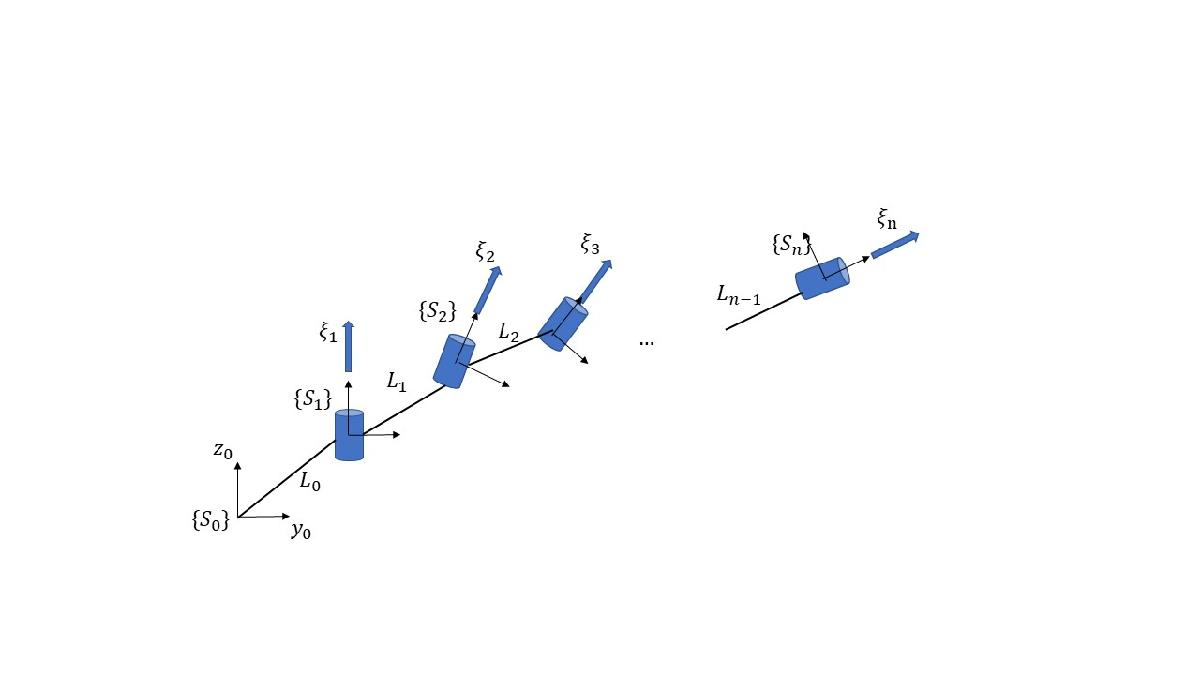

Il twist complessivo tra che rappresenta il moto di {n} rispetto a {0} è esprimibile come:

$V_{0,n} = V_{0,1} + V_{1,2} + ... V_{n-1,n}$    (1)

ovvero, la somma dei twist relativi tra ciascuna coppia di link

Se la parametrizzazione è stata fatta con la local POE, allora è facile scrivere

$V_{i-1,i}^i= \xi_i = X^i\dot{q}_i$ , 

ovvero il twist espresso nelle componenti del frame locale

Per eseguire la somma in (1) è necessario riportare i twist nelle medesime componenti e riferirli allo stesso polo (es. {0} per lo spatial):


$$V_{i-1,i}^0= \textrm{Ad}_{g_{0, i}}X^i\dot{q}_i = J_i(q)\dot{q}_i$$
 

con $g_{0,i} = g_{0,1}(0)e^{\hat{X}q1}g_{1,2}(0)...g_{i-1,i}(0)$

$J_i(q)= \textrm{Ad}_{g_{0,i}}X^i$    è quindi la i-esima colonna dello jacobiano spatial

Jacexpr = spatialJac_localPOE(g0(1:6), X, q, 'EEoffset', g0{7});
Jac = Function('spatialJacobian', {q}, {Jacexpr});

Calcolo del task (postura spada nel tempo)

tmax = 16;
lsl = 0.8;
rals = 0.02;
limp = 0.15;

x = @(t) 0.001.*(...
    800.*(t<=5) +...
    (800 + 150.*(t-5)).*(t>5 & t<=7)+...
    1100.*(t>7 & t<= tmax)...
    ) + 0.3;

y = @(t) 0.001.*(...
    (-400 + 200.*t).*(t<=2) +...
    (1000.*0.5.*limp.*sin(-3./4.*pi+3./8.*pi.*(t-2)).*0.5.*(t-2)).*(t>2 & t <= 4)+...
    0.*(t>4 & t<= tmax)...
    );

z = @(t) 0.001.*(...
    (300 + 200.*t).*(t<=2) +...
    (700+1000.*(0.5.*limp.*sin(pi/4) + 0.5.*limp.*cos(-3/4*pi+3/8*pi.*(t-2))).*0.5.*(t-2)).*(t>2 & t <= 4)+...
    (800+1000.*(lsl - 0.5.*limp).*(t-4)).*(t>4 & t<= 5)+...
    (1525-75.*(t-5)).*(t>5 & t<=7)  +...
    (1375+75.*(t-7)).*(t>7 & t<=8)  +...
    (1450+200.*(t-8)).*(t>8 & t<=9) +...
    (1650-275.*(t-9)).*(t>9 & t<=11)+...
    (1100).*(t>11 & t<= tmax)...
    ) +0.1;

angX = @(t) 3/4*pi.*(t <= 2)+...
            (3/4*pi - 3./8.*pi.*(t-2)).*(t>2 & t<=4)+...
            0.*(t>4 & t<=9)+...
            -1/4*pi.*(t-9).*(t>9 & t<=11)+...
            -1./2.*pi.*(t>11 & t <= tmax);

angY = @(t) 0.*(t<=5)+...
            1/4.*pi.*(t-5).*(t>5 & t<=6)+...
            1/4.*pi.*(t>6 & t<=12)+...
            (1/4.*pi+1./8.*pi.*(t-12)).*(t>12 & t<=tmax);

angZ = @(t) 0.*(t<=11)+...
            1/2*pi.*(t-11).*(t>11 & t<= 12)+...
            1/2.*pi.*(t>12 & t<=tmax);

Gtip = @(t) [rotX(angX(t))*rotY(angY(t))*rotZ(angZ(t)), [x(t); y(t); z(t)]; 0,0,0,1];

dsl = @(t) (0.5*limp-0.005).*(t<4)+...
           ((0.5.*limp - 0.005) + (lsl-0.5.*limp).*(t-4)).*(t>4 & t<=5)+...
           lsl.*(t>5 & t<=tmax);

Tsl_expr = Gtip(t)*RpTohomogeneous(rotZ(-pi/2), [0;0;0])*RpTohomogeneous(eye(3),[0; 0; -dsl(t)]);

Tsl = Function('Tsl', {t}, {Tsl_expr});
p = Function('Tsl', {t}, {Tsl_expr(1:3, 4)});

% calcolo twist spatial del task
V_expr = reshape(jacobian(Tsl_expr, t), 4, 4)*rigidInverse(Tsl_expr);

Integrazione con algoritmo CLIK

Kp = 15;
Ko = 15;
% gain matrix
K = [SX.eye(3).*Kp, SX(3,3); SX(3,3), SX.eye(3).*Ko];

% orientation error with quaternion
% [nT, thetaT] = rotToAxisAngle(Tsl_expr(1:3, 1:3));
% [nE, thetaE] = rotToAxisAngle(Gglobal(1:3, 1:3));
% Qt = axisAngleToQuat(thetaT, nT);
% QE = axisAngleToQuat(thetaE, nE);
% 
% e_o = OerrorFromQuat(Qt, QE);
% https://www.youtube.com/watch?v=yxaEa1OFGgU
% per lezione del prof. Marco Gabiccini

% orientation error with vecForm of skew sym matrix
Rtilde = Tsl_expr(1:3, 1:3)*Gglobal(1:3, 1:3).';
e_o = vecForm(Rtilde - Rtilde.')./2;

% error vector
e = [Tsl_expr(1:3, 4)-Gglobal(1:3, 4); e_o];
% error function
eFun = Function('e', {q, t}, {e});
% 
L = twistRefCLIK(Tsl_expr, Gglobal);
Lbar = [SX.eye(3), SX(3,3); SX(3,3), L];
LT = [SX.eye(3), SX(3,3); SX(3,3), L'];

% integration expression
qdot_expr = pinv(Lbar*Jacexpr)*(LT*vecForm(V_expr) + K*e); % RHS ODE

% integration with runge kutta
dt = 0.01;
t0 = 0;
tend = 15.9999;
qsol = RK4(q, [], qdot_expr, dt, tend, [-pi/2; 0; 0.5; -0.2;-0.5; pi/4+pi/2], t0, [], 't_expr', t);

#### Plotting

Plot robot

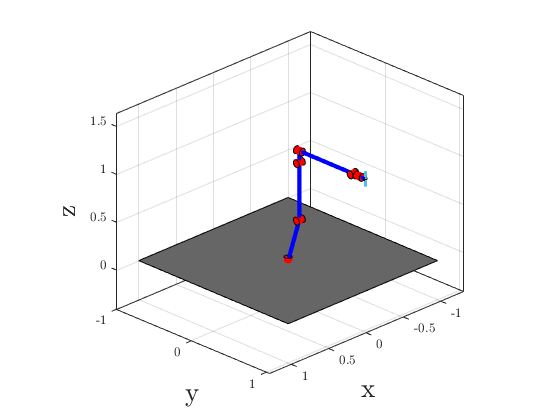

[axes, transforms] = plotRobot_localPOE(GlocalFun, g0, X, zeros(6,1));

% draw a plane
Ppl = [[1;1], [1;-1], [-1;-1], [-1;1]];
patch(axes, Ppl(1,:), Ppl(2,:), zeros(1, 4), 'facecolor', [.4 .4 .4]);
view(135, 25)
xlabel('x', 'fontsize', 20)
ylabel('y', 'fontsize', 20)
zlabel('z', 'fontsize', 20)

Animazione della movimentazione dei giunti

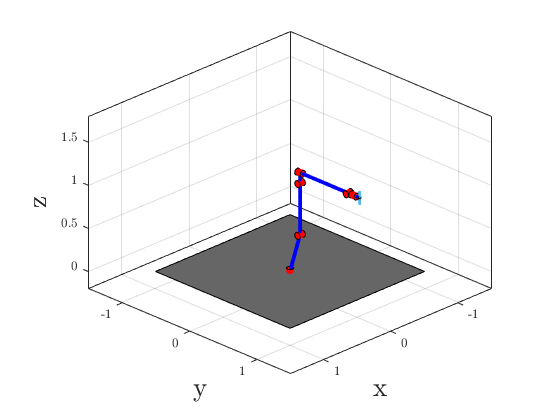

[axes, transforms] = plotRobot_localPOE(GlocalFun, g0, X, zeros(6,1));

% draw a plane
Ppl = [[1;1], [1;-1], [-1;-1], [-1;1]];
patch(axes, Ppl(1,:), Ppl(2,:), zeros(1, 4), 'facecolor', [.4 .4 .4]);
view(135, 25)
xlabel('x', 'fontsize', 20)
ylabel('y', 'fontsize', 20)
zlabel('z', 'fontsize', 20)
set(gcf,'Visible','on')
qnum = zeros(6,1);
val = [linspace(0, pi/4, 30), linspace(pi/4, -pi/4, 60), linspace(-pi/4, 0, 30)];
set(axes, 'xlim', [-1.5 1.5], 'ylim', [-1.5 1.5], 'zlim', [-0.2 1.8])
for j = 1:6
    for i = 1:120
        qnum(j) = val(i);
        updatePlot_localPOE(GlocalFun, qnum, transforms)
        pause(0.01)
    end
end

Task tip blade plot

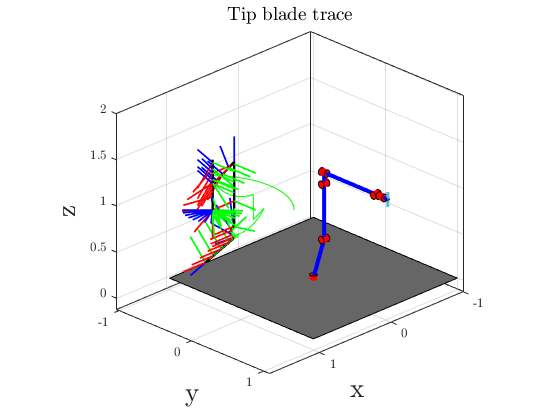

[axes, transforms] = plotRobot_localPOE(GlocalFun, g0, X, zeros(6,1));

% draw a plane
Ppl = [[1;1], [1;-1], [-1;-1], [-1;1]];
patch(axes, Ppl(1,:), Ppl(2,:), zeros(1, 4), 'facecolor', [.4 .4 .4]);
view(135, 25)
xlabel('x', 'fontsize', 20)
ylabel('y', 'fontsize', 20)
zlabel('z', 'fontsize', 20)

tnum = linspace(0,tend, 30);

for i = 1:length(tnum)
    Gt = Gtip(tnum(i));
    plotFrame(Gt, 'scale', 0.3)
end

% draw blade tip line
ttask = linspace(t0, tmax, 500);
line(axes, x(ttask), y(ttask), z(ttask), 'color', 'k', 'linewidth', 1.8);

% draw task line
pos_task = full(p(ttask));
line(axes, pos_task(1,:), pos_task(2,:), pos_task(3,:), 'color', 'g');
title('Tip blade trace', 'FontSize', 14)

Task impugnatura (E-E) plot

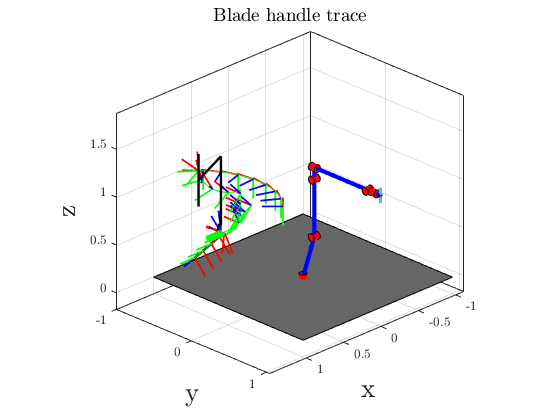

[axes, transforms] = plotRobot_localPOE(GlocalFun, g0, X, zeros(6,1));

% draw a plane
Ppl = [[1;1], [1;-1], [-1;-1], [-1;1]];
patch(axes, Ppl(1,:), Ppl(2,:), zeros(1, 4), 'facecolor', [.4 .4 .4]);
view(135, 25)
xlabel('x', 'fontsize', 20)
ylabel('y', 'fontsize', 20)
zlabel('z', 'fontsize', 20)


tnum = linspace(0,tend, 30);

for i = 1:length(tnum)
    
    G = full(Tsl(tnum(i)));
    plotFrame(G, 'scale', 0.2)
    
end

% draw blade tip line
ttask = linspace(t0, tmax, 500);
line(axes, x(ttask), y(ttask), z(ttask), 'color', 'k', 'linewidth', 1.8);

% draw task line
pos_task = full(p(ttask));
line(axes, pos_task(1,:), pos_task(2,:), pos_task(3,:), 'color', 'g');
title('Blade handle trace', 'FontSize', 14)

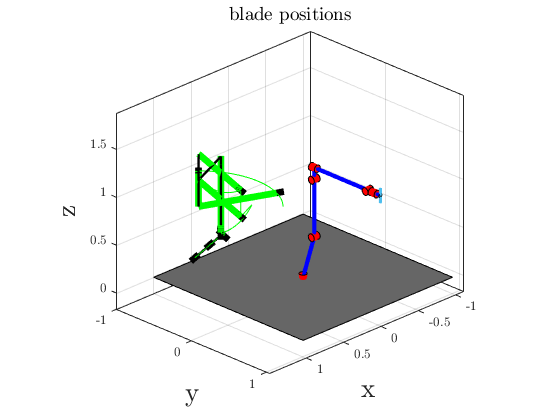

[axes, transforms] = plotRobot_localPOE(GlocalFun, g0, X, zeros(6,1));

% draw a plane
Ppl = [[1;1], [1;-1], [-1;-1], [-1;1]];
patch(axes, Ppl(1,:), Ppl(2,:), zeros(1, 4), 'facecolor', [.4 .4 .4]);
view(135, 25)
xlabel('x', 'fontsize', 20)
ylabel('y', 'fontsize', 20)
zlabel('z', 'fontsize', 20)

tnum = [0, 1, 3, 5, 7, 9, 12, 15];
Xi = [0,0];
Yi = [0,0];
Zi = [-0.5.*limp,0.5.*limp];
Xbi = [0,0];
Ybi = [0,0];
Zbi = [0,lsl];
for i = 1:length(tnum)
    G = full(Tsl(tnum(i))); % calcolo della matrice di trasformazione da {S} all'impugnatura
    
    % plot della traccia dell'impugnatura in questo istante
    Xb = G(1,1).*Xi + G(1,2).*Yi + G(1,3).*Zi + G(1,4); 
    Yb = G(2,1).*Xi + G(2,2).*Yi + G(2,3).*Zi + G(2,4);
    Zb = G(3,1).*Xi + G(3,2).*Yi + G(3,3).*Zi + G(3,4);
    line(Xb, Yb, Zb, 'linewidth', 5, 'color', 'k');
    if tnum(i) > 4
        % plot della traccia della spada accesa in questo istante
        Xb = G(1,1).*Xbi + G(1,2).*Ybi + G(1,3).*Zbi + G(1,4);
        Yb = G(2,1).*Xbi + G(2,2).*Ybi + G(2,3).*Zbi + G(2,4);
        Zb = G(3,1).*Xbi + G(3,2).*Ybi + G(3,3).*Zbi + G(3,4);
        line(Xb, Yb, Zb, 'linewidth', 5, 'color', 'g');
    end
end

% draw blade tip line
ttask = linspace(t0, tmax, 500);
line(axes, x(ttask), y(ttask), z(ttask), 'color', 'k', 'linewidth', 1.8);

% draw task line
pos_task = full(p(ttask));
line(axes, pos_task(1,:), pos_task(2,:), pos_task(3,:), 'color', 'g');

title('blade positions', 'FontSize', 14)

Integraton animation

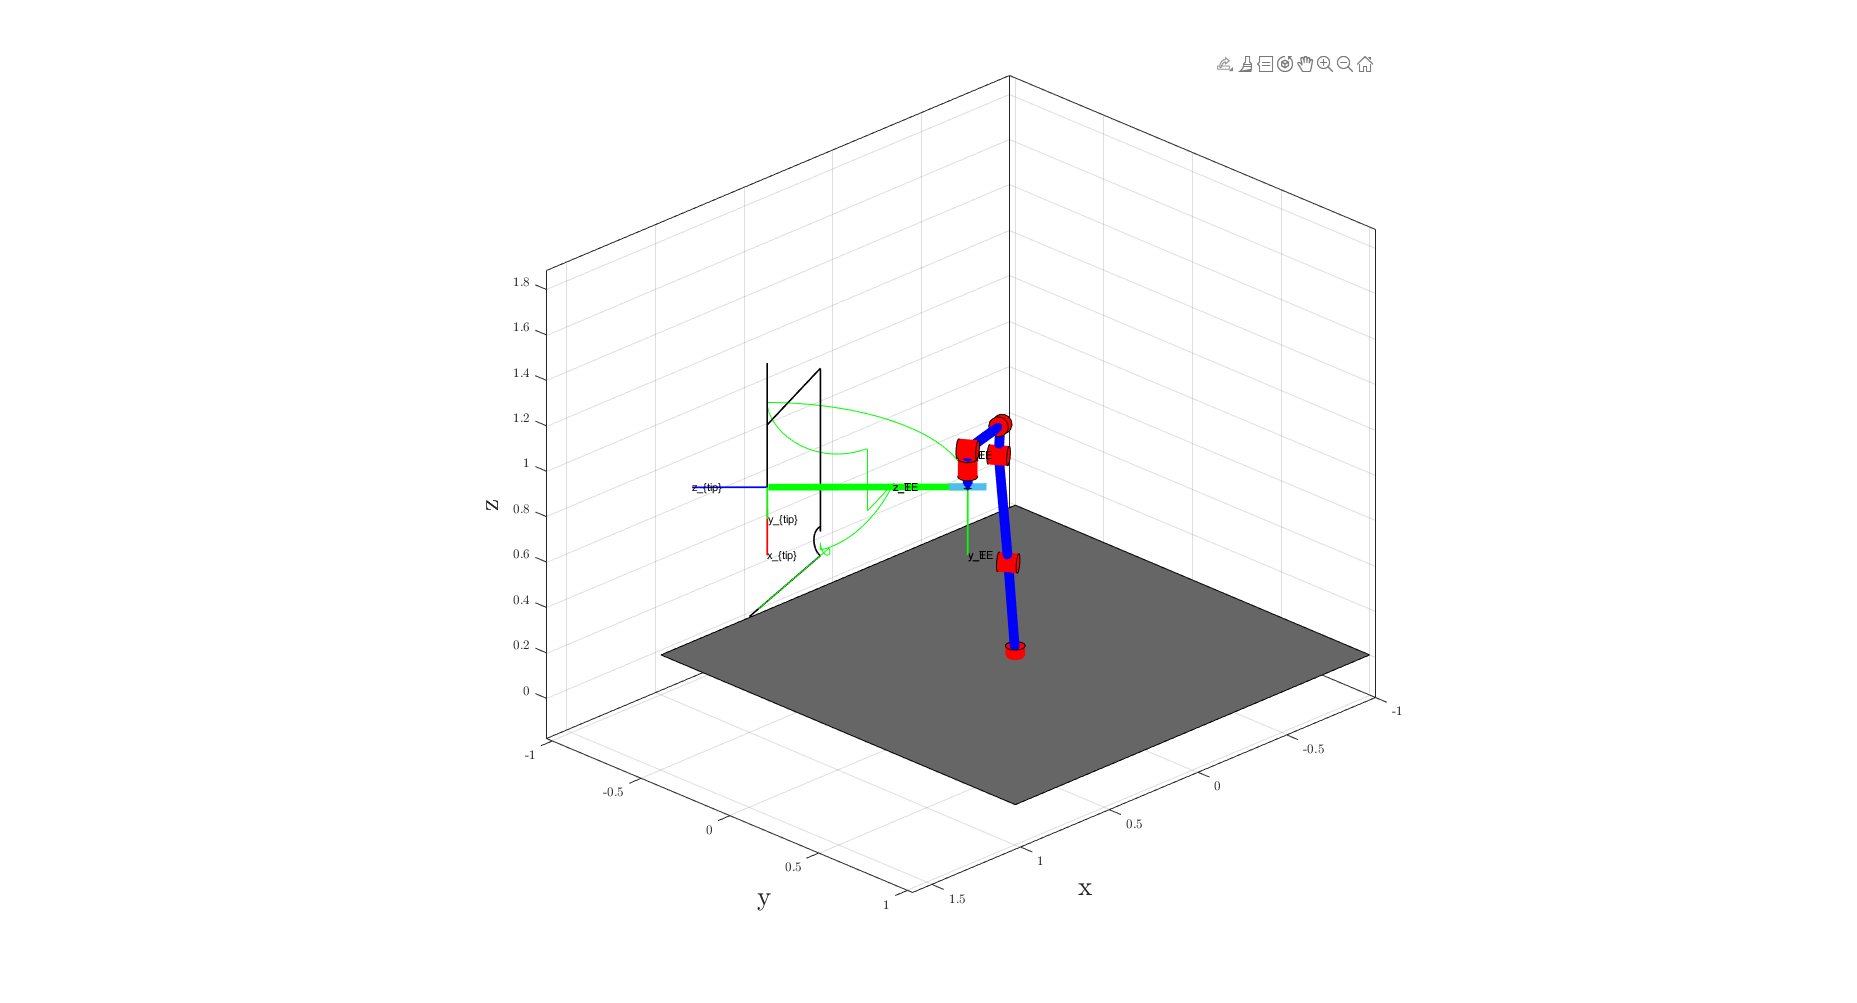

% extract the timeline
tnum = qsol(end, :);

% initialize robot plot
[axes, transforms] = plotRobot_localPOE(GlocalFun, g0, X, [-pi/2; 0; 0.5; -0.2;-0.5; pi/4+pi/2]);

% draw a ground plane
Ppl = [[1;1], [1;-1], [-1;-1], [-1;1]];
patch(axes, Ppl(1,:), Ppl(2,:), zeros(1, 4), 'facecolor', [.4 .4 .4]);

% draw blade tip trace
ttask = linspace(t0, tmax, 500);
line(axes, x(ttask), y(ttask), z(ttask), 'color', 'k', 'linewidth', 1.2);

% draw task line
pos_task = full(p(ttask));
line(axes, pos_task(1,:), pos_task(2,:), pos_task(3,:), 'color', 'g');

% plot settings
view(135, 25)
xlabel('x', 'fontsize', 20)
ylabel('y', 'fontsize', 20)
zlabel('z', 'fontsize', 20)

% popout figure into a new window
set(gcf,'Visible','on')

% set up the transfrom objects
taskFrame_transform = hgtransform('parent', axes);
tip_transform = hgtransform('parent', axes);
eeFrame_transform = hgtransform('parent', transforms{end});
taskFrame_transform.Matrix = full(Tsl(t0));
tip_transform.Matrix = Gtip(0);

% plot frames 
plotFrame(g0{7}, "label", "EE", "parent", eeFrame_transform, "scale", 0.3, "fontSize", 8);
plotFrame(eye(4), "label", "T", "parent", taskFrame_transform, "scale", 0.3, "fontSize", 8);
plotFrame(eye(4), "label", "{tip}", "parent", tip_transform, "scale", 0.3, "fontSize", 8);


% plot blade
bladePlot = line([0,0], [0,0], [-0.5.*limp,0.5.*limp], 'linewidth', 5, 'color', 'g','parent', taskFrame_transform);

% animation loop
for i = 1:size(qsol, 2)
    taskFrame_transform.Matrix = full(Tsl(tnum(i)));
    tip_transform.Matrix = Gtip(tnum(i));
    updatePlot_localPOE(GlocalFun, qsol(1:6, i), transforms)
    if tnum(i) > 4 && tnum(i) < 5   % accensione spada laser
        bladePlot.ZData = [0, (0.5.*limp - 0.005) + (lsl-0.5.*limp).*(tnum(i)-4)];
    end
    pause(0.02)
end

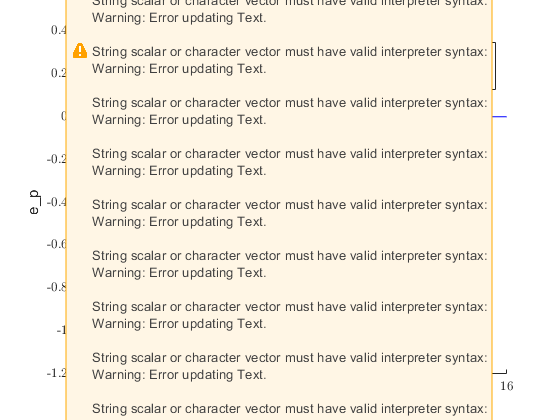


% extract the errors
errors = full(eFun(qsol(1:6,:), tnum));

figure; hold on;
line(tnum, errors(1,:), 'color', 'r')
line(tnum, errors(2,:), 'color', 'g')
line(tnum, errors(3,:), 'color', 'b')
title('positional errors')
legend('X', 'Y', 'Z')
xlabel('t')
ylabel('e_p')

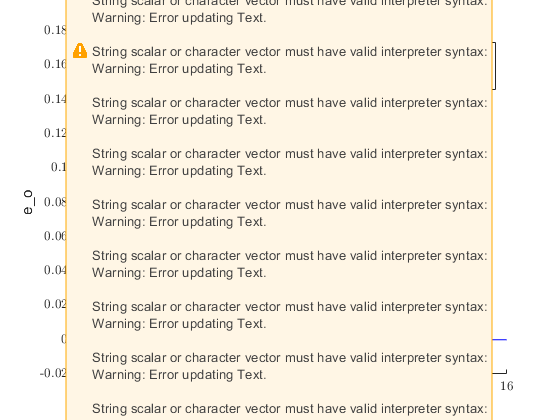


figure; hold on;
line(tnum, errors(4,:), 'color', 'r')
line(tnum, errors(5,:), 'color', 'g')
line(tnum, errors(6,:), 'color', 'b')
title('orientation errors')
legend('Xvec', 'Yvec', 'Zvec')
xlabel('t')
ylabel('e_o')

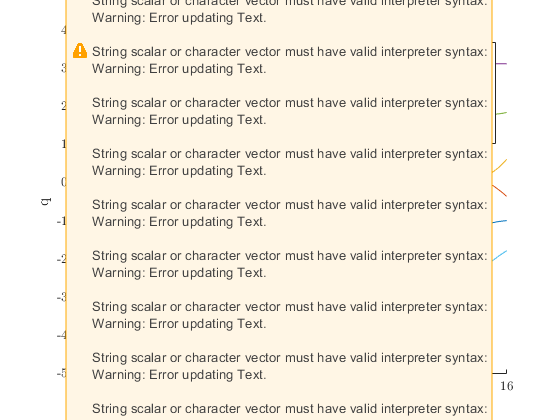


% plot the joint variables
figure; hold on;
plot(tnum, qsol(1,:))
plot(tnum, qsol(2,:))
plot(tnum, qsol(3,:))
plot(tnum, qsol(4,:))
plot(tnum, qsol(5,:))
plot(tnum, qsol(6,:))
title('joint variables')
legend('q_1', 'q_2', 'q_3', 'q_4', 'q_5', 'q_6')
xlabel('t', 'fontsize', 12)
ylabel('q')

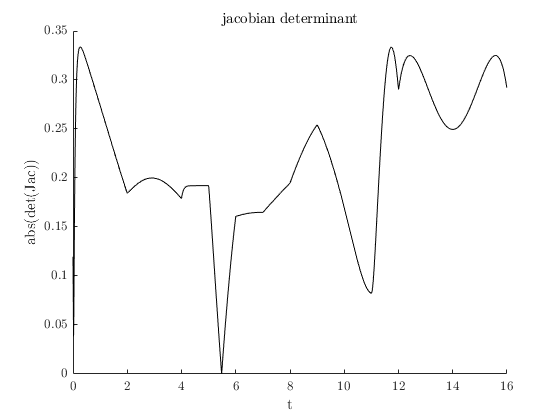

% plot det of the jacobian to detect singularity
Jacnum = reshape(full(Jac(qsol(1:6,:))), 6, 6, length(tnum));
jacdet = nan(1, length(tnum));
for i = 1:length(tnum)
    jacdet(i) = abs(det(Jacnum(:, :, i)));
end

% plot det over time
figure; hold on;
line(tnum, jacdet, 'color', 'k')

title('jacobian determinant')
xlabel('t')
ylabel('abs(det(Jac))')